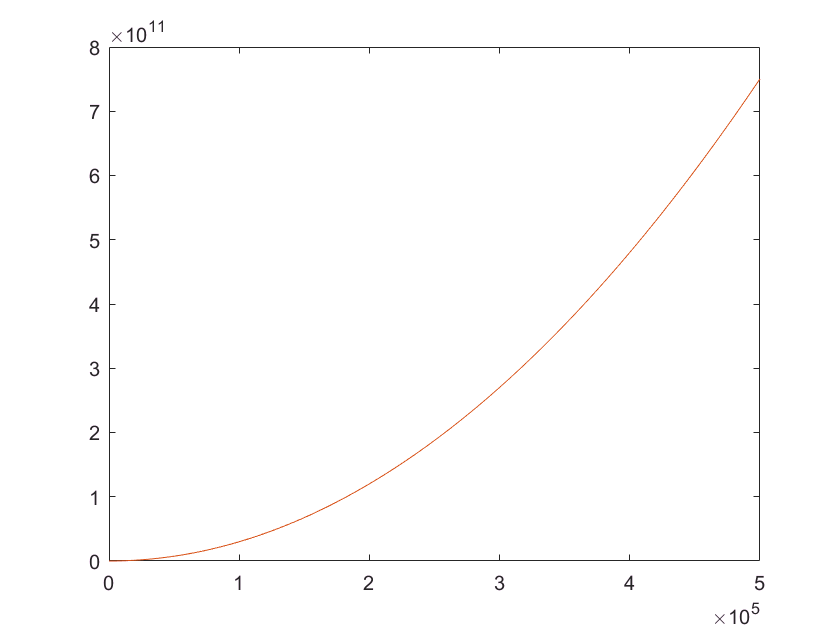

clc; clear; close all;
addpath('functions/');

n = 500000;
sigmaA = 3;
sigmaN = 10;
x1 = 5;
v1 = 1;
t = 1; 
q = 6;
Acc = q + normrnd(0, sigmaA, 1, n );
Noise = normrnd(0, sigmaN, 1, n );
[ X, M  ] = calcTrajectory( Acc, Noise, x1, v1, t);

plot(1:n, X, 1:n, M);

V = M(3:end) - 2*M(2:end-1) + M(1:end-2);
P = M(4:end) - 3*M(2:end-2) + 2*M(1:end-3);

q = mean(V) / t^2;

eV = mean ( (V - q*t^2).^2 );
eP = mean ( (P - 3*q*t^2).^2 );

varianceA = ( (3/7)*eP - eV ) / t^4;
varianceN = eV/6 - (1/12) * varianceA * t^4;

sigmaA_calc = sqrt(varianceA)

sigmaA_calc = 2.8963

sigmaN_calc = sqrt(varianceN)

sigmaN_calc = 9.9951